clear all;
clc;
cstr_global;

global Wc u1 u2
sample_T = 0.1;

n_op = 2;
n_ip = 2;
n_st = 2;
n_d = 2;
N_samples = 500;

G_Ko = 1.0e10;
G_E = 8330.1;
G_V = 1.0;
G_Cp = 1.0;
G_rho = 1e6;
G_delH = 1.3e8;
G_Cpc = 1.0;
G_rhoc = 1e6;
G_a = 1.678e6;
G_b = 0.5;
G_To = 323.0;

state_sigma = [0.001 0.5];
meas_sigma = [0.001 0.5];

u_ss = [1 15]';                                                                    
Uk(:,1) = u_ss;

u1 = 1;
u2 = 15;
C =[1 0;0 1];

Cao = 2.0;
Tcin = 92 + 273;
Wc = [Cao; Tcin];

for i = 1:1:500
    wk(1,i) = state_sigma(1)*randn;
    wk(2,i) = state_sigma(2)*randn;
end

for i = 1:1:500
    vk(1,i) = meas_sigma(1)*randn;
    vk(2,i) = meas_sigma(2)*randn;
end

x_initial = [0.5 400]';

for i = 1:1:500
    [T,Xj] = ode45('cstr_model',[0 sample_T],x_initial);
    X_state(i,:) = Xj(end,:);
    x_initial = Xj(end,:)';
end

set_graphics 

figure(1)
subplot(211)
plot(1:500,X_state(:,1),'b')
ylabel('Ca')
hold ON

subplot(212)
plot(1:500,X_state(:,2),'b')
xlabel('Sampling Instant')
ylabel('T')
hold OFF

X_steady_state = X_state(end,:);

u1_flow = 1 + idinput(500,'PRBS',[0 0.166],[-0.05 0.05]);

u2_temp = 15 + idinput(500,'PRBS',[0 0.166],[-0.75 0.75]);

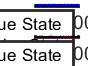


figure(2)
subplot(211)
plot(1:500,u1_flow(:,1),'b')
ylabel('Flow')
hold ON

subplot(212)
plot(1:500,u2_temp(:,1),'b')
xlabel('Sampling Instant')
ylabel('T')
hold OFF

x_initial2 = X_steady_state;
for i = 1:1:N_samples
    u1 = u1_flow(i,1);
    u2 = u2_temp(i,1);
    [T,XM] = ode45('cstr_model',[0 sample_T],x_initial2);
    X_new_state(i,:) = XM(end,:);
    x_initial2=XM(end,:);
    X_noisy_state(i,:) = X_new_state(i,:) + wk(:,i)';
    Yk(:,i) = C*X_noisy_state(i,:)' + vk(:,i);
    u1_flowNoisy(i,1)=u1_flow(i,1)+1*randn;
    u2_tempNoisy(i,1)=u2_temp(i,1)+1*randn;
end

figure(1)
subplot(211)
plot(1:500,X_new_state(:,1),'b', 1:500, X_noisy_state(:,1),'r', 1:500, Yk(1,:)','k')
ylabel('Ca')
legend('True State', 'Noisy State')
hold ON

subplot(212)
plot(1:500,X_new_state(:,2),'b', 1:500, X_noisy_state(:,2),'r',1:500, Yk(2,:)','k')
xlabel('Sampling Instant')
ylabel('T')
legend('True State', 'Noisy State')
hold OFF


x(:,1)=(X_noisy_state(:,1)-mean(X_noisy_state(:,1)))/std(X_noisy_state(:,1));
x(:,2)=(X_noisy_state(:,2)-mean(X_noisy_state(:,2)))/std(X_noisy_state(:,2));
x(:,3)=(u1_flowNoisy-mean(u1_flowNoisy))/std(u1_flowNoisy);
x(:,4)=(u2_tempNoisy-mean(u2_tempNoisy))/std(u2_tempNoisy);

%{
[train_idx, ~, test_idx] = dividerand(500, 0.5, 0,0.5);
    % slice training data with train indexes 
    %(take training indexes in all 10 features)
    x_train = x(train_idx, :);
    % select test data
    x_test = x(test_idx, :);
%}

%{
for i=1:1:350
    x_train(i,:)=x(i,:);
end
for i=1:1:150
    x_test2(i,:)=x(350+i,:);
end
%}

autoenc = trainAutoencoder(x)

autoenc =   Autoencoder with properties:

                 HiddenSize: 10
    EncoderTransferFunction: 'logsig'
             EncoderWeights: [10×500 double]
              EncoderBiases: [10×1 double]
    DecoderTransferFunction: 'logsig'
             DecoderWeights: [500×10 double]
              DecoderBiases: [500×1 double]
         TrainingParameters: [1×1 struct]
                  ScaleData: 1



xReconstructed = predict(autoenc,x)

xReconstructed =    -0.3501   -0.1634   -0.7105   -0.6126
   -0.6951    0.8882   -1.4394   -0.6598
   -0.7499    0.1909    2.8047    0.0750
   -0.8396   -0.1743    0.5883   -1.7427
   -0.5063   -0.1894    0.6063    0.1734
   -0.3652   -0.7650    1.8488    0.5466
   -0.1946   -0.6748   -0.5638   -0.2692
   -0.0192   -0.6641   -0.2933   -0.9408
    0.0094   -0.2078    0.4676   -0.2509
   -0.0968   -0.0801   -0.0742   -0.2541


mseError = mse(x-xReconstructed)

mseError = 0.0033


%---------------------------------------------------------------------------
%{
for i=1:1:500
    if i<=350
        xu1_1(i,1)=u1_flowNoisy(i,1);
    end
    if i>350
        xu1_2(i,1)=u1_flowNoisy(i,1);
    end
end

autoenc=trainAutoencoder(xu1_1(:,1))
xReconstructed = predict(autoenc,xu1_2(:,1))
mseError = mse(xu1_2-xReconstructed)
subplot(211)

plot(1:500,((xu1_2-xReconstructed)/500),'b')

subplot(212)
plot(1:500,xu1_2,'b',1:500,xReconstructed,'r')

%normalise the data
%avg sum of sq data
%find mse error by yourself
%normalize it (value - mean)/standard deviation
%}

figure(3)
subplot(411)
plot(1:500,x(:,1),'b',1:500,xReconstructed(:,1),'r')
xlabel('Sampling Instant')
ylabel('Ca')
legend('True State', 'Reconstructed True State')

subplot(412)
plot(1:500,x(:,2),'b',1:500,xReconstructed(:,2),'r')
xlabel('Sampling Instant')
ylabel('T')
legend('True State', 'Reconstructed True State')


subplot(413)
plot(1:500,x(:,3),'b',1:500,xReconstructed(:,3),'r')
xlabel('Sampling Instant')
ylabel('u1_flow')
legend('True State', 'Reconstructed True State')

subplot(414)
plot(1:500,x(:,4),'b',1:500,xReconstructed(:,4),'r')
xlabel('Sampling Instant')
ylabel('u2_temp')
legend('True State', 'Reconstructed True State')


%NoisyReconstructed=predict(autoenc,Noisy_u1)
%mseErrorNoisy=mse(u1_flowNoisy-Noisy_u1)

for i=1:1:500
    if i<=100
        Noisy_u1(i,1)=u1_flowNoisy(i,1);
    elseif i>100 && i<=150
        Noisy_u1(i,1)=u1_flowNoisy(i,1)+25*randn;
    elseif i>150 && i<=250
        Noisy_u1(i,1)=u1_flowNoisy(i,1);
    elseif i>250 && i<=500
        Noisy_u1(i,1)=i/10+u1_flowNoisy(i,1);
    end
end

plot(1:500,Noisy_u1,'r')
ylabel("Noisy flow")


x_Noisy(:,1)=2*randn+(X_noisy_state(:,1)-mean(X_noisy_state(:,1)))/std(X_noisy_state(:,1));
x_Noisy(:,2)=2*randn+(X_noisy_state(:,2)-mean(X_noisy_state(:,2)))/std(X_noisy_state(:,2));
x_Noisy(:,3)=2*randn+(Noisy_u1-mean(Noisy_u1))/std(Noisy_u1);
x_Noisy(:,4)=2*randn+(u2_tempNoisy-mean(u2_tempNoisy))/std(u2_tempNoisy);

%{
x_Noisy(:,1)=X_noisy_state(:,1);
x_Noisy(:,2)=X_noisy_state(:,2);
x_Noisy(:,3)=Noisy_u1;
x_Noisy(:,4)=u2_tempNoisy;
%}

NoisyxReconstructed = predict(autoenc,x_Noisy)

NoisyxReconstructed =    -0.3519   -0.1753   -0.2341   -0.4689
   -0.7053    0.8624    0.4750   -0.5702
   -0.7518    0.2788   -0.6664    1.6395
   -0.8688   -0.1328   -0.9493    0.3236
   -0.5069   -0.1660   -0.4434    0.1747
   -0.3624   -0.7417   -0.6904    0.6068
   -0.1928   -0.6683   -0.3762   -0.5331
   -0.0197   -0.6418   -0.2668   -0.3157
    0.0051   -0.1892   -0.1876    0.2237
   -0.0977   -0.0813   -0.0931   -0.0938


mseErrorNoisy=mse(x-NoisyxReconstructed)

mseErrorNoisy = 0.7978

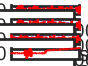


figure(4)
subplot(411)

plot(1:500,x(:,1),'b',1:500,xReconstructed(:,1),'r',1:500,NoisyxReconstructed(:,1),'k')
xlabel('Sampling Instant')
ylabel('Ca')
legend('True State', 'Reconstructed True State','Noisy Reconstructed State')

subplot(412)

plot(1:500,x(:,2),'b',1:500,xReconstructed(:,2),'r',1:500,NoisyxReconstructed(:,2),'k')
xlabel('Sampling Instant')
ylabel('T')
legend('True State', 'Reconstructed True State','Noisy Reconstructed State')

subplot(413)

plot(1:500,x(:,3),'b',1:500,xReconstructed(:,3),'r',1:500,NoisyxReconstructed(:,3),'k')
xlabel('Sampling Instant')
ylabel('u1_flow')
legend('True State', 'Reconstructed True State','Noisy Reconstructed State')

subplot(414)

plot(1:500,x(:,4),'b',1:500,xReconstructed(:,4),'r',1:500,NoisyxReconstructed(:,4),'k')
xlabel('Sampling Instant')
ylabel('u2_temp')
legend('True State', 'Reconstructed True State','Noisy Reconstructed State')



% CNN and autoencoder
% sensors plus abnormality
% including filters

save result_openloop_simulation.mat

